# SCR Prediction approach

Principal component regression

clear;
close all;

basedir = '/Users/clinpsywoo/github/CRB_project/MWW_inprep/scripts';
cd(basedir);

load('../data/CRB_dataset_SCR_lpf5Hz_DS25Hz_011516.mat');

figdir = '../figures';
datdir = '../data';


## Step 1. Creating Y: pain ratings

for i = 1:numel(D.Event_Level.data)
    y_int{i} = D.Event_Level.data{i}(:,12);
    y_unp{i} = -2*(D.Event_Level.data{i}(:,13)-50);
    xx{i} = [D.Event_Level.data{i}(:,11) D.Event_Level.data{i}(:,16) scale(D.Event_Level.data{i}(:,11),1).*scale(D.Event_Level.data{i}(:,16),1)];
    reg{i} = D.Event_Level.data{i}(:,16);
    temp{i} = D.Event_Level.data{i}(:,11);
end

u_temp = unique(temp{1});
u_reg = unique(reg{1});

for subj = 1:numel(temp)
    for i = 1:numel(u_temp)
        for j = 1:numel(u_reg)
            dat_int{i,j}(subj,1) = nanmean(y_int{subj}(temp{subj}==u_temp(i) & reg{subj}==u_reg(j)));
            dat_unp{i,j}(subj,1) = nanmean(y_unp{subj}(temp{subj}==u_temp(i) & reg{subj}==u_reg(j)));
        end
    end
end


## Step 2. Creating X: SCR data (averaged over three trials)

for j = 1:numel(D.Continuous.data)      % loop through subjects
    
    scr = D.Continuous.data{j};         % SCR data for each person
    
    ons = D.Event_Level.data{j}(:,5);   % Heat onset 
    
    for ii = 1:6
        for jj = 1:3
            signal{j}.cond{ii, jj} = [];  % pre-allocation 
        end
    end
        
    for i = 1:numel(ons)
        temp_lev = D.Event_Level.data{j}(i,11)-43;  % temperature level 1-6
        reg_lev = D.Event_Level.data{j}(i,16)+2;    % regulation level 1-3
        a = round((ons(i)-3)*25);                   % onset in 25 Hz
        signal{j}.cond{temp_lev, reg_lev}(end+1,:) = scr(a:(a+(23*25))); 
                                                    % get data for 23 seconds
    end
end

clear signal_m;
k = 0;

for i = 1:6
    for j = 1:3
        k = k + 1;
        for subj = 1:numel(signal)
            signal_m{i,j}(subj,:) = mean(signal{subj}.cond{i,j} - repmat(mean(signal{subj}.cond{i,j}(:,1:75),2), 1, size(signal{subj}.cond{i,j},2)));
                                                     % subtracting the baseline, and then average
        end
    end
end


## Step 3. Running PCR 

3-1. Determining the number of components of the model

addpath('/Users/clinpsywoo/github/canlabrepo/CanlabCore/CanlabCore/External/lasso');

for i = 1:6
    for j = 1:3
        subjs{i,j} = (1:size(dat_int{i,j},1))';  % ready for leave-one-participant-out (LOPO) cross-validation
    end
end

dat.int = fmri_data;                                 % to use fmri_data.predict function, 
                                                 % put the data in fmri_data object
dat.int.Y = cat(1,dat_int{:,2});                     % add concatenated intensity ratings in dat.Y
dat.int.dat = cat(1,signal_m{:,2})';                 % add concatenated epoch data in dat.dat
                                                 % **For the training, we only used passive experience runs.**
dat.int.dat = dat.int.dat(76:575,:);                     % Stimulus-locked 20 seconds epoch 
whfolds = cat(1,subjs{:,2});                     % cross-validaion folds (LOPO CV)

dat.unp = dat.int;
dat.unp.Y = cat(1,dat_unp{:,2});  

savename = fullfile(datdir, 'SCR_prediction_dat_112816.mat');
save(savename, '-append', 'dat', 'whfolds', 'dat_int', 'dat_unp', 'signal_m');

clear rmse pred_outcome_r;

for i = 2:10
    if i == 2, disp('SCR predictive model for intensity ratings'); end
    [~, stats_int, ~] = predict(dat.int, 'algorithm_name', 'cv_pcr', 'nfolds', whfolds, 'numcomponents', i, 'verbose', 0);
    rmse.int(i-1) = stats_int.rmse;
    
    for j = unique(whfolds)'
        por_subj(j) = corr(stats_int.Y(whfolds==j), stats_int.yfit(whfolds==j));
    end
    
    pred_outcome_r.int(i-1) = mean(por_subj);
    fprintf('\n #component = %d, rmse = %1.4f, pred_outcome_r = %1.4f', i, stats_int.rmse, mean(por_subj));
end

SCR predictive model for intensity ratings



 #component = 2, rmse = 10.8866, pred_outcome_r = 0.8311


 #component = 3, rmse = 10.9629, pred_outcome_r = 0.8305


 #component = 4, rmse = 11.0066, pred_outcome_r = 0.8192


 #component = 5, rmse = 11.0720, pred_outcome_r = 0.8145


 #component = 6, rmse = 11.1408, pred_outcome_r = 0.8013


 #component = 7, rmse = 11.2035, pred_outcome_r = 0.7940


 #component = 8, rmse = 11.2930, pred_outcome_r = 0.7880


 #component = 9, rmse = 11.4732, pred_outcome_r = 0.7765


 #component = 10, rmse = 11.5011, pred_outcome_r = 0.7744

clear por_subj;

for i = 2:10
    if i == 2, disp('SCR predictive model for unpleasantness ratings'); end
    [~, stats_unp, ~] = predict(dat.unp, 'algorithm_name', 'cv_pcr', 'nfolds', whfolds, 'numcomponents', i, 'verbose', 0);
    rmse.unp(i-1) = stats_unp.rmse;
    
    for j = unique(whfolds)'
        por_subj(j) = corr(stats_unp.Y(whfolds==j), stats_unp.yfit(whfolds==j));
    end
    
    pred_outcome_r.unp(i-1) = mean(por_subj);
    fprintf('\n #component = %d, rmse = %1.4f, pred_outcome_r = %1.4f', i, stats_unp.rmse, mean(por_subj));
end

SCR predictive model for unpleasantness ratings



 #component = 2, rmse = 13.1948, pred_outcome_r = 0.7615


 #component = 3, rmse = 13.3685, pred_outcome_r = 0.7562


 #component = 4, rmse = 13.3780, pred_outcome_r = 0.7478


 #component = 5, rmse = 13.4781, pred_outcome_r = 0.7423


 #component = 6, rmse = 13.4935, pred_outcome_r = 0.7476


 #component = 7, rmse = 13.5896, pred_outcome_r = 0.7451


 #component = 8, rmse = 13.5482, pred_outcome_r = 0.7427


 #component = 9, rmse = 13.6391, pred_outcome_r = 0.7350


 #component = 10, rmse = 13.5639, pred_outcome_r = 0.7285

3-2. Plot for rmse and pred_outcome_r for different numbers of components

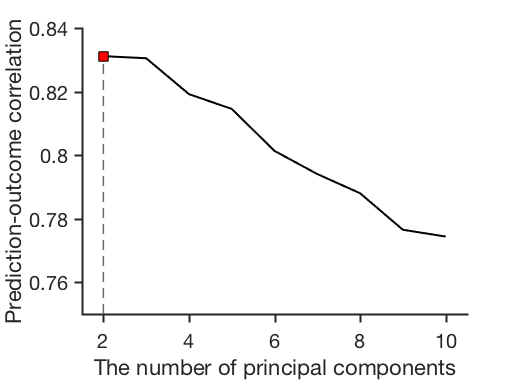

savefig = 0;

[~, x] = max(-scale(rmse.int)+scale(pred_outcome_r.int));

create_figure('por'); 

% [hAx,hLine1,hLine2] = plotyy(2:10, pred_outcome_r.int, 2:10, rmse.int);
% 
% hLine1.LineWidth = 2.5;
% hLine2.LineWidth = 2.5;
% 
% set(gca, 'box', 'off', 'tickdir', 'out', 'tickLength', [.02 .02]);
% set(gcf, 'Position', [360   238   694   460]);
% set(hAx(1), 'FontSize', 22, 'LineWidth', 1.5, 'xlim', [1.5 10.5], 'ylim', [.48 .56], 'ytick', .48:.02:.56);
% set(hAx(2), 'tickdir', 'out', 'tickLength', [.018 .018], 'FontSize', 22, 'LineWidth', 1.5, 'xlim', [1.5 10.5], 'ylim', [10.8 11.6], 'ytick', 10.8:.2:11.6);

plot(2:10, pred_outcome_r.int, 'color', 'k', 'linewidth', 2);
if ~savefig
    xlabel('The number of principal components', 'fontsize', 20);
    ylabel('Prediction-outcome correlation', 'fontsize', 20);
end

y = pred_outcome_r.int(x);

hold on;
line([x+1 x+1], [0.35 y], 'linestyle', '--', 'color', [.4 .4 .4], 'linewidth', 1.5);
scatter(x+1, y, 150, 'r', 'marker', 's', 'markerfacecolor', 'r', 'markeredgecolor', 'k');
set(gca, 'tickDir', 'out', 'tickLength', [.02 .02], 'linewidth', 2, 'ylim', [.75 .84], 'xlim', [1.5, 10.5], 'fontsize', 20);

if ~savefig
    set(gcf, 'position', [360   318   516   380]);
else
    set(gcf, 'position', [360   455   338   243]);
end

if savefig
    savename = fullfile(figdir, 'prediction_outcome_int_ncomp.pdf');
    pagesetup(gcf);
    saveas(gcf, savename);
    
    pagesetup(gcf);
    saveas(gcf, savename);
end


Similar results for RMSE.. decided not to put this figure in the paper.

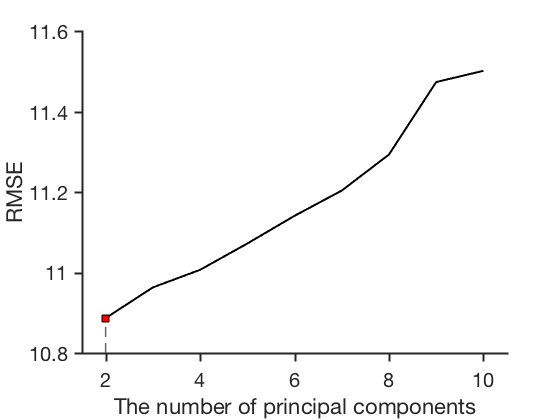

close all;
create_figure('rmse'); 
plot(2:10, rmse.int, 'color', 'k', 'linewidth', 2);
xlabel('The number of principal components', 'fontsize', 22);
ylabel('RMSE', 'fontsize', 22);

hold on;

y = rmse.int(x);

line([x+1 x+1], [10.8 y], 'linestyle', '--', 'color', [.4 .4 .4], 'linewidth', 1.5);
scatter(x+1, y, 80, 'r', 'marker', 's', 'markerfacecolor', 'r', 'markeredgecolor', 'k');

set(gca, 'tickDir', 'out', 'tickLength', [.02 .02], 'linewidth', 2, 'fontsize', 20, 'xlim', [1.5 10.5]);


% figdir = '/Users/clinpsywoo/Dropbox (CANLAB)/c_crb_analysis/analysis_n25/figure';
% savename = fullfile(figdir, 'rmse_int_ncomp.pdf');
% try
%     pagesetup(gcf);
%     saveas(gcf, savename);
% catch
%     pagesetup(gcf);
%     saveas(gcf, savename);
% end

3-3. PCR model for intensity ratings with NCOMP = 2, bootstrapping 10000


[~, pcr_stats.int, ~] = predict(dat.int, 'algorithm_name', 'cv_pcr', 'nfolds', whfolds, 'numcomponents', 2, 'bootweights', 'bootsamples', 10000); % run it again
[~, pcr_stats.unp, ~] = predict(dat.unp, 'algorithm_name', 'cv_pcr', 'nfolds', whfolds, 'numcomponents', 2, 'bootweights', 'bootsamples', 10000); % run it again

save(fullfile(datdir, 'SCR_prediction_dat_112816.mat'), '-append', 'pcr_stats', 'pred_outcome_r', 'rmse');


3-4. See weights, significant time points

3-4-1. Plot for intensity 

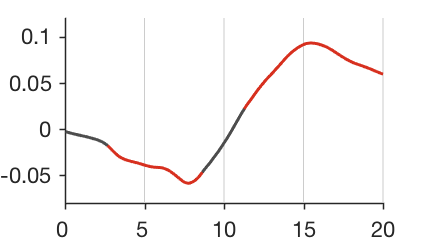

close all;

load(fullfile(datdir, 'SCR_prediction_dat_112816.mat'));

x = 1:500;
create_figure('PCR weights');

for i = (5:5:20)*25
    line([i i], [-.3 1], 'col', [.8 .8 .8], 'linewidth', 1);
end

sig_idx = pcr_stats.int.WTS.wP<getFDR(pcr_stats.int.WTS.wP, .05);
% significant time points = [67:215 282:500]
idx{1} = 1:67;
idx{2} = 216:282;
idx{3} = 67:216;
idx{4} = 282:500;
for i = 1:2, plot(x(idx{i}), pcr_stats.int.other_output{1}(idx{i}), 'color', [.3 .3 .3], 'linewidth', 3); end
for i = 3:4, plot(x(idx{i}), pcr_stats.int.other_output{1}(idx{i}), 'color', [0.8431    0.1882    0.1216], 'linewidth', 3); end

set(gcf, 'position', [50   208   423   242]);
set(gca, 'ylim', [-.08 .12], 'xlim', [0 500], 'linewidth', 1.5, 'TickDir', 'out', 'TickLength', [.02 .02], 'Xtick', (0:5:24)*25, 'ytick', -.05:.05:.12);
set(gca, 'XTickLabel', get(gca, 'XTick')./25);
set(gca, 'fontSize', 22);

savename = fullfile(figdir, 'SCR_intensity_predictive_weights.pdf');

pagesetup(gcf);
saveas(gcf, savename);

pagesetup(gcf);
saveas(gcf, savename);

3-4-2. Plot for unpleasantness

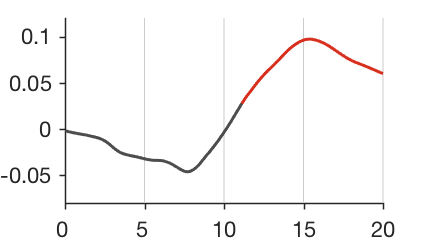

close all;

x = 1:500;
create_figure('PCR weights');

for i = (5:5:24)*25
    line([i i], [-.3 1], 'col', [.8 .8 .8], 'linewidth', 1);
end

sig_idx = pcr_stats.unp.WTS.wP<getFDR(pcr_stats.unp.WTS.wP, .05);
% significant time points = [278:500]
idx{1} = 1:278;
idx{2} = 278:500;
i=1; plot(x(idx{i}), pcr_stats.unp.other_output{1}(idx{i}), 'color', [.3 .3 .3], 'linewidth', 3); 
i=2; plot(x(idx{i}), pcr_stats.unp.other_output{1}(idx{i}), 'color', [0.8431    0.1882    0.1216], 'linewidth', 3); 

set(gcf, 'position', [50   208   423   242]);
set(gca, 'ylim', [-.08 .12], 'xlim', [0 500], 'linewidth', 1.5, 'TickDir', 'out', 'TickLength', [.02 .02], 'Xtick', (0:5:24)*25, 'ytick', -.05:.05:.12);
set(gca, 'XTickLabel', get(gca, 'XTick')./25);
set(gca, 'fontSize', 22);

savename = fullfile(figdir, 'SCR_unpleasantness_predictive_weights.pdf');

pagesetup(gcf);
saveas(gcf, savename);

pagesetup(gcf);
saveas(gcf, savename);


fprintf('\ncorrelation between intensity and unpleasantness weights r = %1.3f\n', corr(pcr_stats.int.other_output{1}, pcr_stats.unp.other_output{1}));


correlation between intensity and unpleasantness weights r = 0.998


## Step 4. Testing on regulation trials

scr = load(fullfile(datdir, 'SCR_prediction_dat_112816.mat'));

% Applying the model on regulation trials using leave-one-participant-out cross validation
for i = [1 3]
    for j = 1:6
        for subj = 1:size(scr.signal_m{j,i},1)
            test_scr_int{j,i}(subj,1) = scr.signal_m{j,i}(subj,76:575)*scr.pcr_stats.int.other_output_cv{subj,1} + scr.pcr_stats.int.other_output_cv{subj,2};
            test_scr_unp{j,i}(subj,1) = scr.signal_m{j,i}(subj,76:575)*scr.pcr_stats.unp.other_output_cv{subj,1} + scr.pcr_stats.unp.other_output_cv{subj,2};
        end
    end
end

temp_int = reshape(scr.pcr_stats.int.yfit, 41, 6);
temp_unp = reshape(scr.pcr_stats.unp.yfit, 41, 6);

for j = 1:6
    test_scr_int{j,2} = temp_int(:,j);
    test_scr_unp{j,2} = temp_unp(:,j);
end

save(fullfile(datdir, 'SCR_prediction_dat_112816.mat'), '-append', 'test_scr_*');

% scatter plot
y_int = [cat(2,scr.dat_int{:,1}) cat(2,scr.dat_int{:,3})];
yfit_int = [cat(2,test_scr_int{:,1}) cat(2,test_scr_int{:,3})];

y_unp = [cat(2,scr.dat_unp{:,1}) cat(2,scr.dat_unp{:,3})];
yfit_unp = [cat(2,test_scr_int{:,1}) cat(2,test_scr_int{:,3})];


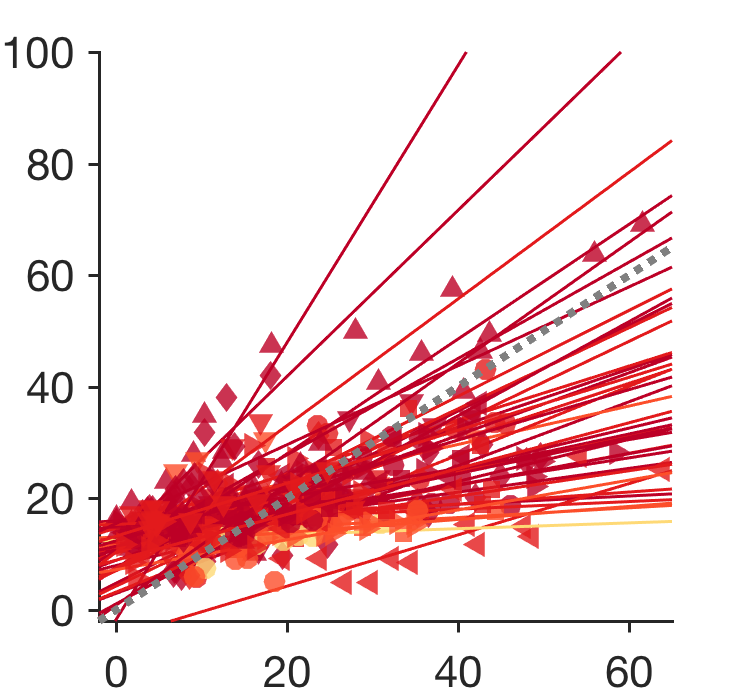

colors = [255,237,160
254,217,118
254,178,76
253,141,60
252,78,42
227,26,28
189,0,38]./255;

xlim = [-2 65];
create_figure('predicted');

clear test_por;
for i = 1:size(y_int,1)
    hold on;
    x = y_int(i,:);
    y = yfit_int(i,:);
    b = glmfit(x,y);
    test_por(i) = corr(x',y');
end

dif = 1/size(colors,1);

k = zeros(size(test_por));
for i = 1:size(colors,1)
    idx = test_por <= (dif*i+.0001) & test_por >= dif*(i-1);
    k(idx) = i;
end

marker_shapes = repmat('osd^v><', 1, 40);

for i = 1:size(y_int,1)
    hold on;
    x = y_int(i,:);
    y = yfit_int(i,:);
    b = glmfit(x,y);
    line_h(i) = line(xlim, b'*[ones(1,2); xlim], 'linewidth', 1.5, 'color', colors(k(i),:)); % cmap(round(i*1.5),:));
    scatter(x, y, 120, colors(k(i),:), 'filled', 'markerfacealpha', .8, 'marker', marker_shapes(i));
end

line(xlim, xlim, 'linewidth', 4, 'linestyle', ':', 'color', [.5 .5 .5]);

set(gcf, 'position', [360   349   371   349]);
set(gca, 'tickdir', 'out', 'TickLength', [.02 .02], 'linewidth', 1.5, 'xlim', xlim, 'ylim', [-2 100], 'fontsize', 22);

savename = fullfile(figdir, 'SCR_actual_predicted_outcomes.pdf');

pagesetup(gcf);
saveas(gcf, savename);

pagesetup(gcf);
saveas(gcf, savename);

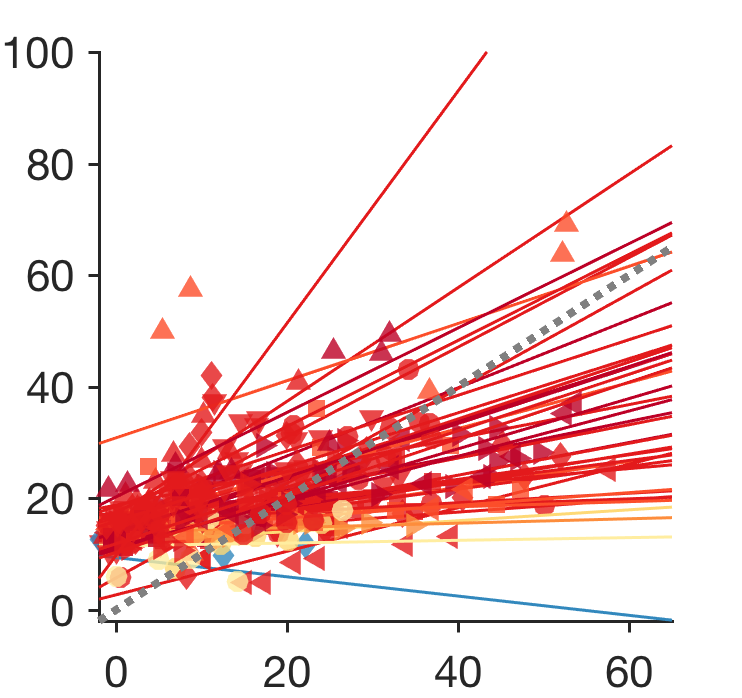



create_figure('predicted_unp');
dif = 1/size(colors,1);

clear test_por_unp;
for i = 1:size(y_unp,1)
    hold on;
    x = y_unp(i,:);
    y = yfit_unp(i,:);
    b = glmfit(x,y);
    test_por_unp(i) = corr(x',y');
end

k = zeros(size(test_por_unp));
for i = 1:size(colors,1)
    idx = test_por_unp <= (dif*i+.0001) & test_por_unp >= dif*(i-1);
    k(idx) = i;
end

marker_shapes = repmat('osd^v><', 1, 40);

for i = 1:size(y_unp,1)
    hold on;
    x = y_unp(i,:);
    y = yfit_unp(i,:);
    b = glmfit(x,y);
    try
        line_h(i) = line(xlim, b'*[ones(1,2); xlim], 'linewidth', 1.5, 'color', colors(k(i),:)); % cmap(round(i*1.5),:));
        scatter(x, y, 120, colors(k(i),:), 'filled', 'markerfacealpha', .8, 'marker', marker_shapes(i));
    catch
        line_h(i) = line(xlim, b'*[ones(1,2); xlim], 'linewidth', 1.5, 'color', [0.1961    0.5333    0.7412]); % cmap(round(i*1.5),:));
        scatter(x, y, 120, [0.1961    0.5333    0.7412], 'filled', 'markerfacealpha', .8, 'marker', marker_shapes(i));
    end
    
end

line(xlim, xlim, 'linewidth', 4, 'linestyle', ':', 'color', [.5 .5 .5]);

set(gcf, 'position', [360   349   371   349]);
set(gca, 'tickdir', 'out', 'TickLength', [.02 .02], 'linewidth', 1.5, 'xlim', xlim, 'ylim', [-2 100], 'fontsize', 22);

savename = fullfile(figdir, 'SCR_actual_predicted_outcomes_unpleasant.pdf');

pagesetup(gcf);
saveas(gcf, savename);

pagesetup(gcf);
saveas(gcf, savename);



fprintf('\nTest results: mean prediction_outcome_r for intensity = %1.3f', mean(test_por));


Test results: mean prediction_outcome_r for intensity = 0.823

fprintf('\nTest results: mean prediction_outcome_r for unpleasantness = %1.3f', mean(test_por_unp));


Test results: mean prediction_outcome_r for unpleasantness = 0.731

## Step 5. Test the effects of temperature and regulation on SCR pattern response

5-1. Intensity

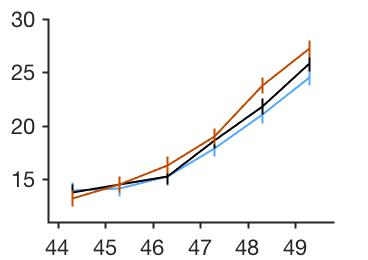

load('../data/CRB_dataset_SCR_lpf5Hz_DS25Hz_011516.mat');
load(fullfile(datdir, 'SCR_prediction_dat_112816.mat'));

clear reg_all;

for i = 1:numel(D.Event_Level.data)
    reg{i} = D.Event_Level.data{i}(:,16);
    temp{i} = D.Event_Level.data{i}(:,11);
end

% dosavefig = false; % save figure in matlab 2014 (was written in 2014 previously)
figdir = '../figures';

reg_all{1} = cat(2,test_scr_int{:,1})';
reg_all{2} = cat(2,test_scr_int{:,2})';
reg_all{3} = cat(2,test_scr_int{:,3})';

x = 44.3:1:49.3;
y = [mean(reg_all{1},2) mean(reg_all{2},2) mean(reg_all{3},2)];
% se = [repmat(wsbar(reg_all{1}'), 6, 1) repmat(wsbar(reg_all{2}'), 6, 1) repmat(wsbar(reg_all{3}'), 6, 1)];
se = repmat(barplot_get_within_ste([reg_all{1}; reg_all{2}; reg_all{3}]'), 6, 3);


create_figure('plot');
set(gcf, 'position', [360   438   368   260]);

col = [0.3333    0.6588    1.0000
       0         0         0
       0.7608    0.3020    0];

for i = 1:3
    hold on;
    h = errorbar(x, y(:,i), se(:,i), 'color', col(i,:), 'linewidth', 2); %, 'markersize', 4, 'markerfacecolor', col(i,:));
    % sepplot(x, y(:,i), .75, 'color', col(i,:), 'linewidth', 2);
    % if dosavefig, errorbar_width(h, x, [0 0]); end
    h.CapSize = 0;
end

set(gca, 'xlim', [43.8 49.8], 'linewidth', 2, 'xtick', 44:49, 'tickdir',...
    'out', 'ticklength', [.02 .02], 'ytick', 15:5:30, 'ylim', [11 30]);

set(gca, 'fontsize', 22);

%figdir = '/Users/clinpsywoo/Dropbox (CANLAB)/c_crb_analysis/analysis/figure';
savename = fullfile(figdir, 'test_scr_int.pdf');
pagesetup(gcf);
saveas(gcf, savename);

pagesetup(gcf);
saveas(gcf, savename);

5-2. Unpleasantness

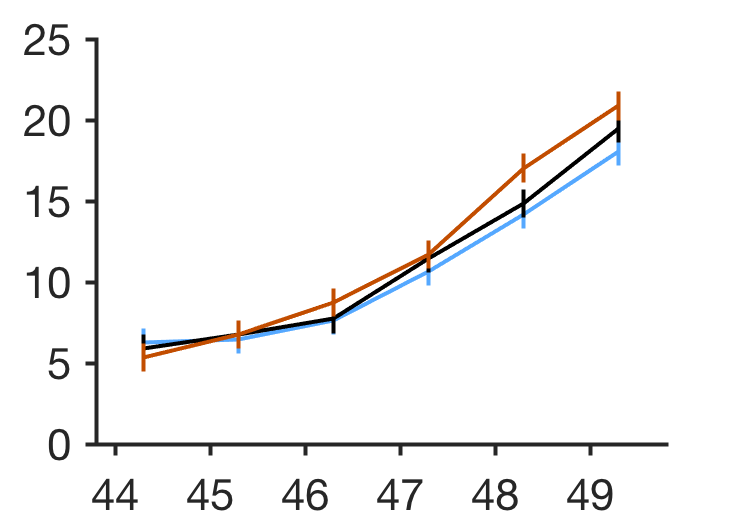


reg_all{1} = cat(2,test_scr_unp{:,1})';
reg_all{2} = cat(2,test_scr_unp{:,2})';
reg_all{3} = cat(2,test_scr_unp{:,3})';

x = 44.3:1:49.3;
y = [mean(reg_all{1},2) mean(reg_all{2},2) mean(reg_all{3},2)];
% se = [repmat(wsbar(reg_all{1}'), 6, 1) repmat(wsbar(reg_all{2}'), 6, 1) repmat(wsbar(reg_all{3}'), 6, 1)];
se = repmat(barplot_get_within_ste([reg_all{1}; reg_all{2}; reg_all{3}]'), 6, 3);

create_figure('plot');
set(gcf, 'position', [360   438   368   260]);

col = [0.3333    0.6588    1.0000
       0         0         0
       0.7608    0.3020    0];

for i = 1:3
    hold on;
    h = errorbar(x, y(:,i), se(:,i), 'color', col(i,:), 'linewidth', 2); %, 'markersize', 4, 'markerfacecolor', col(i,:));
    % sepplot(x, y(:,i), .75, 'color', col(i,:), 'linewidth', 2);
    % if dosavefig, errorbar_width(h, x, [0 0]); end
    h.CapSize = 0;
end

set(gca, 'xlim', [43.8 49.8], 'linewidth', 2, 'xtick', 44:49, 'tickdir',...
    'out', 'ticklength', [.02 .02], 'ytick', 0:5:25, 'ylim', [0 25]);
set(gca, 'fontsize', 22);

%figdir = '/Users/clinpsywoo/Dropbox (CANLAB)/c_crb_analysis/analysis/figure';
savename = fullfile(figdir, 'test_scr_unp.pdf');
pagesetup(gcf);
saveas(gcf, savename);

pagesetup(gcf);
saveas(gcf, savename);

5-3. multilevel GLM analysis for SCR intensity 

temp = repmat(1:6, 1, 3)';
reg = [ones(6,1)*-1; zeros(6,1); ones(6,1)*1];
for i = 1:size(test_scr_int{1},1)
    xx{i} = [temp reg scale(temp,1).*scale(reg,1)];
    
    kk = 0;
    for k = 1:3
        for j = 1:6
            kk = kk + 1;
            yy_int{i}(kk,1) = test_scr_int{j,k}(i);
            yy_unp{i}(kk,1) = test_scr_unp{j,k}(i);
        end
    end
end
glm_scr_int = glmfit_multilevel(yy_int, xx, [], 'names', {'intcp', 'temp', 'reg', 'intera'}, ...
    'verbose', 'boot', 'nresample', 10000);

Analysis description: Second Level of Multilevel Model  
GLS analysis

Observations:  41, Predictors:   1
Outcome names: intcp	temp	reg	intera	
Weighting option: unweighted
Inference option: bootstrap

Other Options:
	Plots: No
	Robust: no
	Save: No
	Output file: glmfit_general_output.txt
	 Min p-value is 0.000000. Needed: 10000 samples
 Bootstrapping 10000 samples... Bootstrap done in 0.00 s, bias correct in 0.00 s 
Total time: 0.65 s

________________________________________
Average p-value tolerance (average max alpha): 0.0060

Bootstrapped statistics. Bootstrap inference
	Outcome variables:
	intcp	temp	reg	intera	
Adj. mean	9.66	2.50	0.61	0.34	

2nd-level B01
	intcp	temp	reg	intera	
Coeff	9.66	2.50	0.61	0.34	
STE	0.64	0.33	0.18	0.09	
t	14.98	7.55	3.37	3.78	
Z	2.92	4.79	4.12	3.66	
p	0.0017	0.0000	0.0000	0.0001	

________________________________________


for SCR unpleasantness


glm_scr_unp = glmfit_multilevel(yy_unp, xx, [], 'names', {'intcp', 'temp', 'reg', 'intera'}, ...
    'verbose', 'boot', 'nresample', 10000);

Analysis description: Second Level of Multilevel Model  
GLS analysis

Observations:  41, Predictors:   1
Outcome names: intcp	temp	reg	intera	
Weighting option: unweighted
Inference option: bootstrap

Other Options:
	Plots: No
	Robust: no
	Save: No
	Output file: glmfit_general_output.txt
	 Min p-value is 0.000000. Needed: 10000 samples
 Bootstrapping 10000 samples... Bootstrap done in 0.01 s, bias correct in 0.00 s 
Total time: 0.65 s

________________________________________
Average p-value tolerance (average max alpha): 0.0060

Bootstrapped statistics. Bootstrap inference
	Outcome variables:
	intcp	temp	reg	intera	
Adj. mean	1.39	2.78	0.61	0.38	

2nd-level B01
	intcp	temp	reg	intera	
Coeff	1.39	2.78	0.61	0.37	
STE	0.70	0.38	0.19	0.10	
t	1.96	7.27	3.19	3.79	
Z	1.32	4.91	3.92	3.66	
p	0.0936	0.0000	0.0000	0.0001	

________________________________________


5-4. Plotting GLM results

Intensity

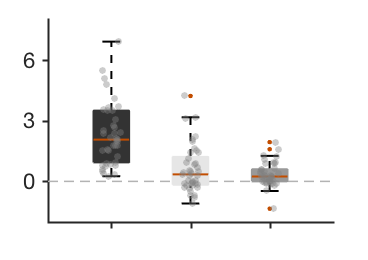

load(fullfile(datdir, 'SCR_prediction_dat_112816.mat'));

dosavefig = true;
edgecolor = 'k';
facecolor = [.2 .2 .2;
    .9 .9 .9;
    .6 .6 .6];

close all;
boxplot_wani_2016(glm_scr_int.first_level.beta(2:4,:)', 'color', facecolor, 'refline', 0, 'linewidth', 2, 'boxlinewidth', 3);
set(gcf, 'position', [360   438   368   260]);
set(gca, 'fontsize', 22, 'linewidth', 2, 'ticklength', [.02 .02], 'ylim', [-2 8], 'ytick', [0:3:9]);

h = scatter(reshape(repmat(1:3, 41, 1), 41*3,1)+scale(rand(41*3,1))/15, ...
    reshape(glm_scr_int.first_level.beta(2:4,:)', 41*3,1), 50, [.5 .5 .5], 'filled', 'MarkerFaceAlpha', .4);

savename = fullfile(figdir, 'test_scr_int_glm_box.pdf');

pagesetup(gcf);
saveas(gcf, savename);

pagesetup(gcf);
saveas(gcf, savename);


Unpleasantness

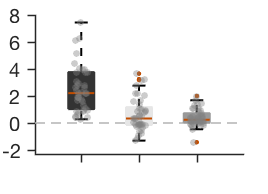


close all;
boxplot_wani_2016(glm_scr_unp.first_level.beta(2:4,:)', 'color', facecolor, 'refline', 0, 'linewidth', 2, 'boxlinewidth', 3);
set(gcf, 'position',  [1   512   268   194]);
set(gca, 'fontsize', 20, 'linewidth', 1.5, 'ticklength', [.04 .04], 'ylim', [-2.3 8]);

h = scatter(reshape(repmat(1:3, 41, 1), 41*3,1)+scale(rand(41*3,1))/15, ...
    reshape(glm_scr_int.first_level.beta(2:4,:)', 41*3,1), 50, [.5 .5 .5], 'filled', 'MarkerFaceAlpha', .4);

if dosavefig
    savename = fullfile(figdir, 'test_scr_unp_glm_box.pdf');
    
    pagesetup(gcf);
    saveas(gcf, savename);
    
    pagesetup(gcf);
    saveas(gcf, savename);
else
    set(gca, 'fontsize', 15);
    xticklabels({'temp', 'reg', 'int'});
    ylabel('Effect magnitude', 'fontsize', 18);
    ylabel('Regressors', 'fontsize', 18);
end

5-5. Test passive vs. down

temp = repmat(1:6, 1, 3)';
reg = [ones(6,1)*-1; zeros(6,1); ones(6,1)*1];

%% passive vs. down

clear yy_int yy_unp;

for i = 1:size(test_scr_int{1},1)
    xx{i} = [temp(1:12) scale(reg(1:12),1) scale(temp(1:12),1).*scale(reg(1:12),1)];
    
    kk = 0;
    for k = 1:2
        for j = 1:6
            kk = kk + 1;
            yy_int{i}(kk,1) = test_scr_int{j,k}(i);
            yy_unp{i}(kk,1) = test_scr_unp{j,k}(i);
        end
    end
end

glm_scr_int1 = glmfit_multilevel(yy_int, xx, [], 'names', {'intcp', 'temp', 'reg', 'intera'}, ...
     'verbose', 'boot', 'nresample', 10000);

Analysis description: Second Level of Multilevel Model  
GLS analysis

Observations:  41, Predictors:   1
Outcome names: intcp	temp	reg	intera	
Weighting option: unweighted
Inference option: bootstrap

Other Options:
	Plots: No
	Robust: no
	Save: No
	Output file: glmfit_general_output.txt
	 Min p-value is 0.000000. Needed: 10000 samples
 Bootstrapping 10000 samples... Bootstrap done in 0.01 s, bias correct in 0.00 s 
Total time: 0.76 s

________________________________________
Average p-value tolerance (average max alpha): 0.0060

Bootstrapped statistics. Bootstrap inference
	Outcome variables:
	intcp	temp	reg	intera	
Adj. mean	10.00	2.31	0.51	0.26	

2nd-level B01
	intcp	temp	reg	intera	
Coeff	9.99	2.32	0.51	0.26	
STE	0.65	0.33	0.30	0.18	
t	15.24	7.00	1.69	1.43	
Z	2.92	4.72	1.53	0.99	
p	0.0018	0.0000	0.0630	0.1616	

________________________________________



glm_scr_unp1 = glmfit_multilevel(yy_unp, xx, [], 'names', {'intcp', 'temp', 'reg', 'intera'}, ...
    'verbose', 'boot', 'nresample', 10000);

Analysis description: Second Level of Multilevel Model  
GLS analysis

Observations:  41, Predictors:   1
Outcome names: intcp	temp	reg	intera	
Weighting option: unweighted
Inference option: bootstrap

Other Options:
	Plots: No
	Robust: no
	Save: No
	Output file: glmfit_general_output.txt
	 Min p-value is 0.000000. Needed: 10000 samples
 Bootstrapping 10000 samples... Bootstrap done in 0.01 s, bias correct in 0.00 s 
Total time: 0.67 s

________________________________________
Average p-value tolerance (average max alpha): 0.0060

Bootstrapped statistics. Bootstrap inference
	Outcome variables:
	intcp	temp	reg	intera	
Adj. mean	1.76	2.59	0.50	0.31	

2nd-level B01
	intcp	temp	reg	intera	
Coeff	1.76	2.59	0.49	0.31	
STE	0.71	0.38	0.33	0.20	
t	2.45	6.72	1.46	1.53	
Z	1.72	4.81	1.19	1.12	
p	0.0424	0.0000	0.1162	0.1308	

________________________________________


5-6. Test up vs. passive



clear yy_int yy_unp;

for i = 1:size(test_scr_int{1},1)
    xx{i} = [temp(7:18) scale(reg(7:18),1) scale(temp(7:18),1).*scale(reg(7:18),1)];
    
    kk = 0;
    for k = 2:3
        for j = 1:6
            kk = kk + 1;
            yy_int{i}(kk,1) = test_scr_int{j,k}(i);
            yy_unp{i}(kk,1) = test_scr_unp{j,k}(i);
        end
    end
end

glm_scr_int2 = glmfit_multilevel(yy_int, xx, [], 'names', {'intcp', 'temp', 'reg', 'intera'}, ...
     'verbose', 'boot', 'nresample', 10000);

Analysis description: Second Level of Multilevel Model  
GLS analysis

Observations:  41, Predictors:   1
Outcome names: intcp	temp	reg	intera	
Weighting option: unweighted
Inference option: bootstrap

Other Options:
	Plots: No
	Robust: no
	Save: No
	Output file: glmfit_general_output.txt
	 Min p-value is 0.000000. Needed: 10000 samples
 Bootstrapping 10000 samples... Bootstrap done in 0.00 s, bias correct in 0.00 s 
Total time: 0.54 s

________________________________________
Average p-value tolerance (average max alpha): 0.0060

Bootstrapped statistics. Bootstrap inference
	Outcome variables:
	intcp	temp	reg	intera	
Adj. mean	9.39	2.66	0.70	0.43	

2nd-level B01
	intcp	temp	reg	intera	
Coeff	9.40	2.66	0.70	0.42	
STE	0.66	0.35	0.38	0.18	
t	14.00	7.59	1.80	2.28	
Z	2.87	4.73	1.64	2.21	
p	0.0021	0.0000	0.0500	0.0136	

________________________________________



glm_scr_unp2 = glmfit_multilevel(yy_unp, xx, [], 'names', {'intcp', 'temp', 'reg', 'intera'}, ...
     'verbose', 'boot', 'nresample', 10000);

Analysis description: Second Level of Multilevel Model  
GLS analysis

Observations:  41, Predictors:   1
Outcome names: intcp	temp	reg	intera	
Weighting option: unweighted
Inference option: bootstrap

Other Options:
	Plots: No
	Robust: no
	Save: No
	Output file: glmfit_general_output.txt
	 Min p-value is 0.000000. Needed: 10000 samples
 Bootstrapping 10000 samples... Bootstrap done in 0.01 s, bias correct in 0.00 s 
Total time: 0.69 s

________________________________________
Average p-value tolerance (average max alpha): 0.0060

Bootstrapped statistics. Bootstrap inference
	Outcome variables:
	intcp	temp	reg	intera	
Adj. mean	1.05	2.96	0.72	0.44	

2nd-level B01
	intcp	temp	reg	intera	
Coeff	1.05	2.96	0.72	0.44	
STE	0.74	0.40	0.42	0.20	
t	1.41	7.32	1.71	2.13	
Z	0.74	4.89	1.55	1.99	
p	0.2304	0.0000	0.0604	0.0232	

________________________________________


mean(glm_scr_int2.first_level.beta(3,:)'-glm_scr_int1.first_level.beta(3,:)')

ans = 0.1816

[~, p, ~, tstat] = ttest(glm_scr_int2.first_level.beta(3,:)'-glm_scr_int1.first_level.beta(3,:)')

p = 0.7620

tstat = 다음 필드를 포함한 struct :
    tstat: 0.3049
       df: 40
       sd: 3.8123


mean(glm_scr_unp2.first_level.beta(3,:)'-glm_scr_unp1.first_level.beta(3,:)')

ans = 0.2274

[~, p, ~, tstat] = ttest(glm_scr_unp2.first_level.beta(3,:)'-glm_scr_unp1.first_level.beta(3,:)')

p = 0.7324

tstat = 다음 필드를 포함한 struct :
    tstat: 0.3443
       df: 40
       sd: 4.2286
